根据CAS号, 从数据库中找到对应物质的物性数据

以苯为例子, CAS = 71-43-2

CAS = '71-43-2';
C6H6 = Component(CAS);

- Ename, 英文名字, -

Ename = C6H6.Ename

Ename = 'Benzene'

- Pc, 临界压力, Pa

Pc = C6H6.Pc

Pc =      4895000


- Tc, 临界温度, K

Tc = C6H6.Tc

Tc =      5.620500000000000e+02


- Vc, 临界体积, $\frac{m^3 }{\textrm{kmol}}$

Vc = C6H6.Vc

Vc =    0.256000000000000


- Zc, 临界压缩因子,  -

Zc = C6H6.Zc

Zc =    0.268000000000000


- Tb, 常压沸点温度, K

Tb = C6H6.Tb

Tb =      3.532400000000000e+02


- Ttriple, 三相点温度, K

Ttriple = C6H6.Ttriple

Ttriple =      2.786800000000000e+02


- Ptriple, 三相点压力, Pa

Ptriple = C6H6.Ptriple

Ptriple =      4.764220000000000e+03


- Mw, 摩尔质量, $\frac{\textrm{kg}}{\textrm{kmol}}$

Mw = C6H6.Mw

Mw =   78.114000000000004


- $\omega \;$, 偏心因子, -

omega = C6H6.omega

omega =    0.209000000000000


- ${H^m }_{\textrm{form}}$ , 标准摩尔生成焓, $\frac{J}{\textrm{kmol}}$

Hfrom = C6H6.Hform

Hfrom =     82880000


- ${G^m }_{\textrm{from}}$ , 标准摩尔生成自由能, $\frac{J}{\textrm{kmol}}$

Gform = C6H6.Gform

Gform =    129600000


- LiquidDensity, 液体的密度, kmol/m^3

- 
$$\rho_L =\frac{A}{B^{\left(1+{\left(1-\frac{T}{C}\right)}^D \right)} }$$


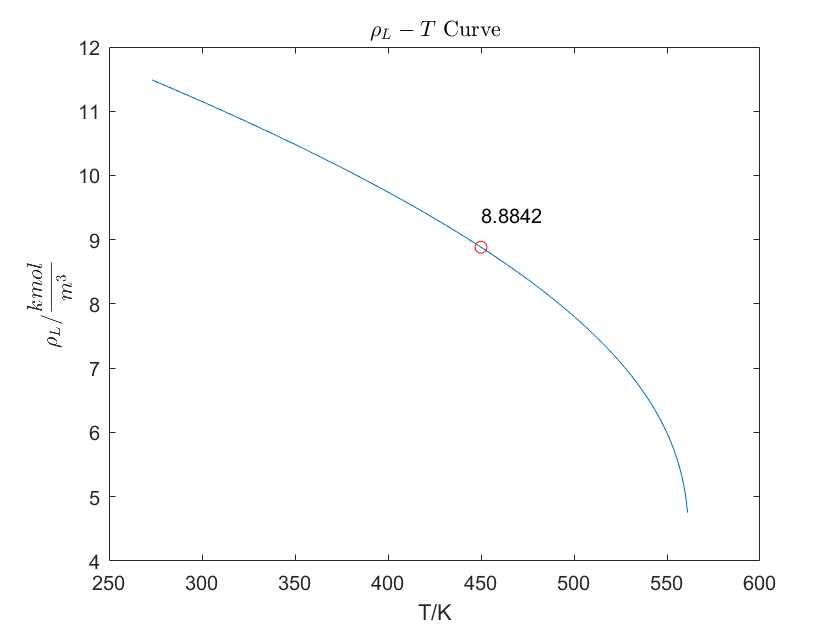


plot([ C6H6.LiquidDensity(end-1):C6H6.LiquidDensity(end) ], C6H6.LiquidDensity_func( [C6H6.LiquidDensity(end-1):C6H6.LiquidDensity(end) ] ))
hold on
plot(450,  C6H6.LiquidDensity_func(450), 'or')
text(450,  C6H6.LiquidDensity_func(450)+0.5, num2str(C6H6.LiquidDensity_func(450)) )
hold off
title('$${\rho_L-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')
ylabel('$${ \rho_L/ \frac{kmol}{m^3} }$$', 'Interpreter', 'latex')

- VaporPressure, 饱和蒸汽压, Pa

- 
$$P^* =e^{\left(A+\frac{B}{T}+C*\ln \left(T\right)+D*T^E \right)}$$


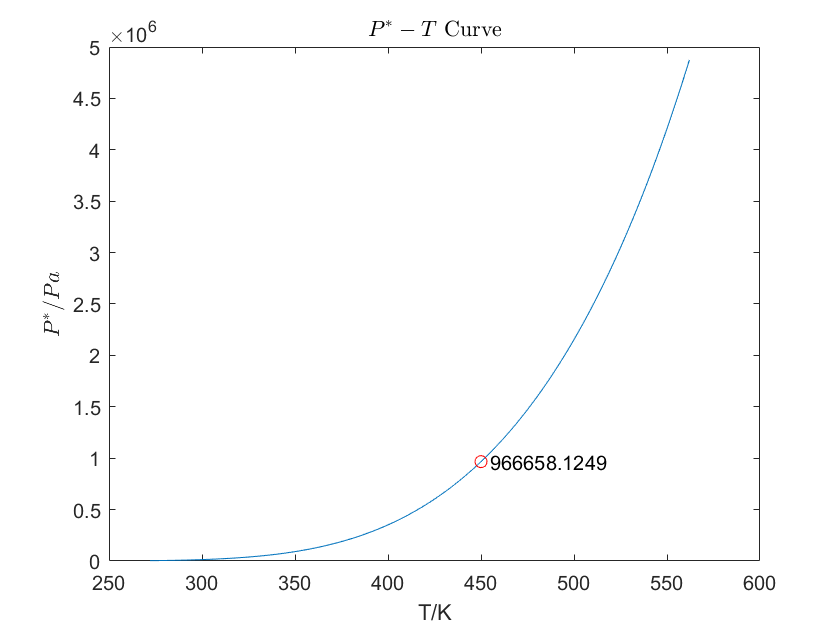

plot([ C6H6.VaporPressure(end-1):C6H6.VaporPressure(end) ], C6H6.VaporPressure_func( [C6H6.VaporPressure(end-1):C6H6.VaporPressure(end) ] ))
hold on
plot(450,  C6H6.VaporPressure_func(450), 'or')
text(455,  C6H6.VaporPressure_func(450), num2str(C6H6.VaporPressure_func(450)) )
hold off
title('$${P^*-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')
ylabel('$${ P^*/Pa }$$', 'Interpreter', 'latex')

- HeatOfVaporization, 标准摩尔蒸发焓, J/kmol

- 
$$\Delta {H^m }_{\textrm{vap}} =A*{\left(1-T_r \right)}^{\left(B+C*T_r +D*T_r^2 +E*T_r^3 \right)} ,T_r =\frac{T}{\textrm{Tc}}$$


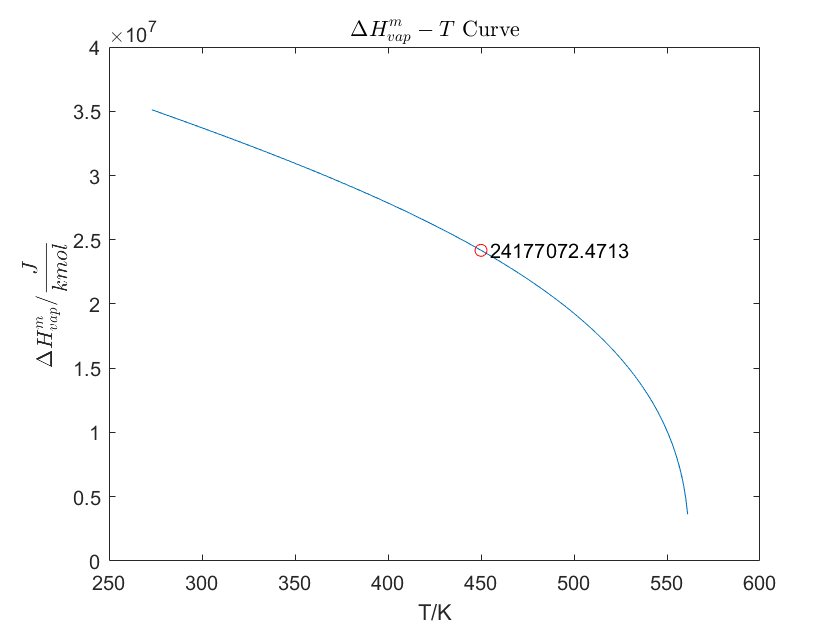

plot([ C6H6.HeatOfVaporization(end-1):C6H6.HeatOfVaporization(end) ], C6H6.HeatOfVaporization_func( [C6H6.HeatOfVaporization(end-1):C6H6.HeatOfVaporization(end) ] ))
hold on
plot(450,  C6H6.HeatOfVaporization_func(450), 'or')
text(455,  C6H6.HeatOfVaporization_func(450), num2str(C6H6.HeatOfVaporization_func(450)) )
hold off
title('$${\Delta H^m_{vap}-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')
ylabel('$${\Delta H^m_{vap}/ \frac{J}{kmol}}$$', 'Interpreter', 'latex')

- LiquidHeatCapacityCp, 液体等压比热容, J/kmol/K

- 
$${C_{P,L} }^m =A+e^{\left(\frac{B}{T}+C+D*T+E*T^2 \right)}$$


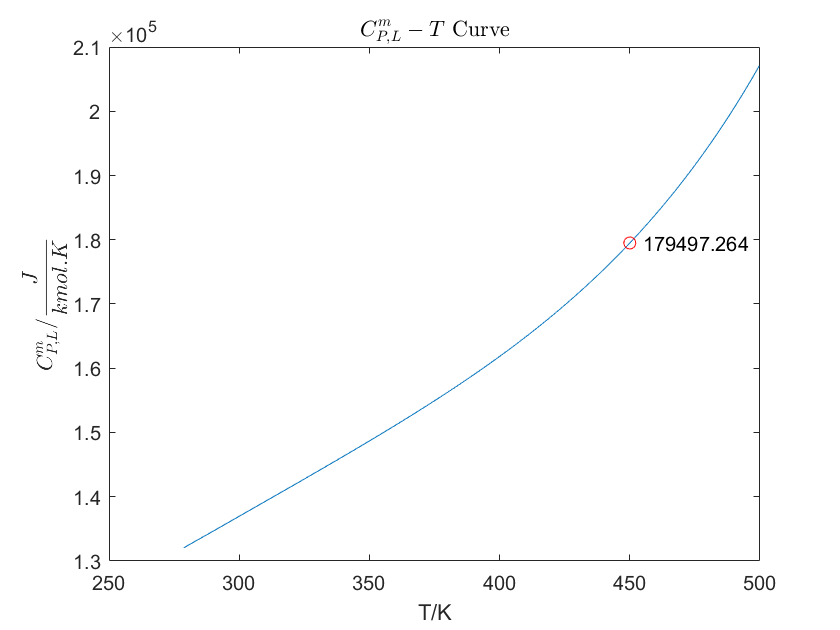

plot([ C6H6.LiquidHeatCapacityCp(end-1):C6H6.LiquidHeatCapacityCp(end) ], C6H6.LiquidHeatCapacityCp_func( [C6H6.LiquidHeatCapacityCp(end-1):C6H6.LiquidHeatCapacityCp(end) ] ))
hold on
plot(450,  C6H6.LiquidHeatCapacityCp_func(450), 'or')
text(455,  C6H6.LiquidHeatCapacityCp_func(450), num2str(C6H6.LiquidHeatCapacityCp_func(450)) )
hold off
title('$${C^m_{P,L}-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')
ylabel('$${C^m_{P,L}/ \frac{J}{kmol.K}}$$', 'Interpreter', 'latex')

- IdealGasHeatCapacityCp, 理想气体等压比热容, J/kmol/K

- 
$${C_{P,V} }^{m,\textrm{ideal}} =A+e^{\left(\frac{B}{T}+C+D*T+E*T^2 \right)}$$


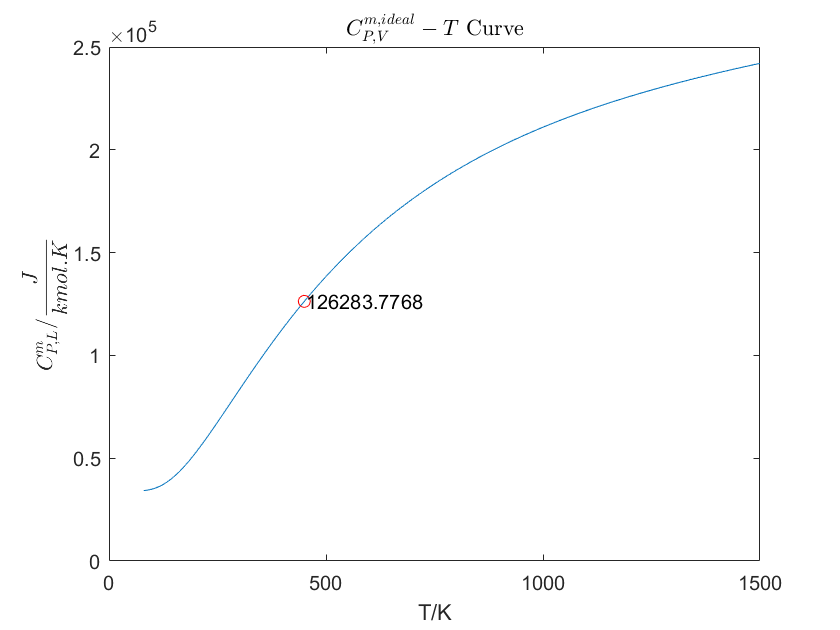

plot([ C6H6.IdealGasHeatCapacityCp(end-1):C6H6.IdealGasHeatCapacityCp(end) ], C6H6.IdealGasHeatCapacityCp_func( [C6H6.IdealGasHeatCapacityCp(end-1):C6H6.IdealGasHeatCapacityCp(end) ] ))
hold on
plot(450,  C6H6.IdealGasHeatCapacityCp_func(450), 'or')
text(455,  C6H6.IdealGasHeatCapacityCp_func(450), num2str(C6H6.IdealGasHeatCapacityCp_func(450)) )
hold off
title('$${C^{m,ideal}_{P,V}-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')
ylabel('$${C^m_{P,L}/ \frac{J}{kmol.K}}$$', 'Interpreter', 'latex')

- LiquidViscosity, 液体粘度, Pa.s

- 
$$\mu_L =e^{\left(A+\frac{B}{T}+\textrm{Cln}\left(T\right)+D*T^E \right)}$$


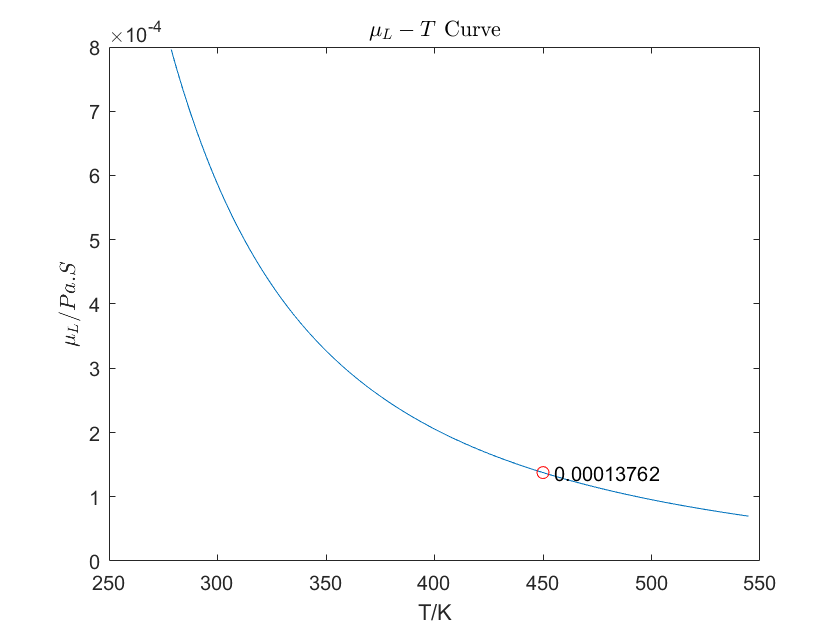

plot([ C6H6.LiquidViscosity(end-1):C6H6.LiquidViscosity(end) ], C6H6.LiquidViscosity_func( [ C6H6.LiquidViscosity(end-1):C6H6.LiquidViscosity(end) ] ))
hold on
plot(450,  C6H6.LiquidViscosity_func(450), 'or')
text(455,  C6H6.LiquidViscosity_func(450), num2str(C6H6.LiquidViscosity_func(450)) )
hold off
title('$${\mu_L-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')
ylabel('$${\mu_L/ Pa.S}$$', 'Interpreter', 'latex')

- VaporViscosity, 气体粘度, Pa.s

- 
$$\mu_V =\frac{A*T^B }{\left(1+\frac{C}{T}+\frac{D}{T^2 }\right)}$$


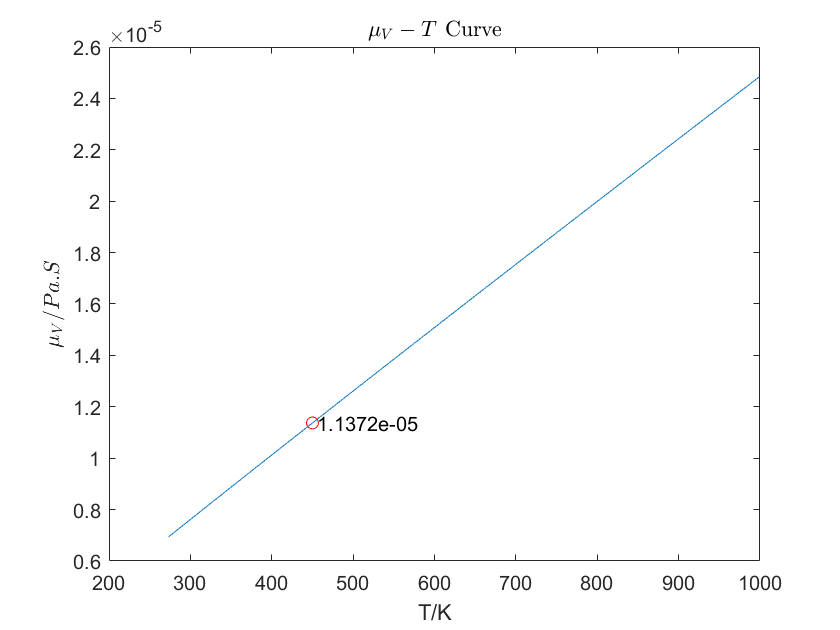

plot([ C6H6.VaporViscosity(end-1):C6H6.VaporViscosity(end) ], C6H6.VaporViscosity_func( [C6H6.VaporViscosity(end-1):C6H6.VaporViscosity(end) ] ))
hold on
plot(450,  C6H6.VaporViscosity_func(450), 'or')
text(455,  C6H6.VaporViscosity_func(450), num2str(C6H6.VaporViscosity_func(450)) )
hold off
title('$${\mu_V-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')
ylabel('$${\mu_V/ Pa.S}$$', 'Interpreter', 'latex')

- LiquidThermalConductivity, 液体导热系数, W/m/K

- 
$$\lambda_L =A+e^{\left(\frac{B}{T}+C+D*T+E*T^2 \right)}$$


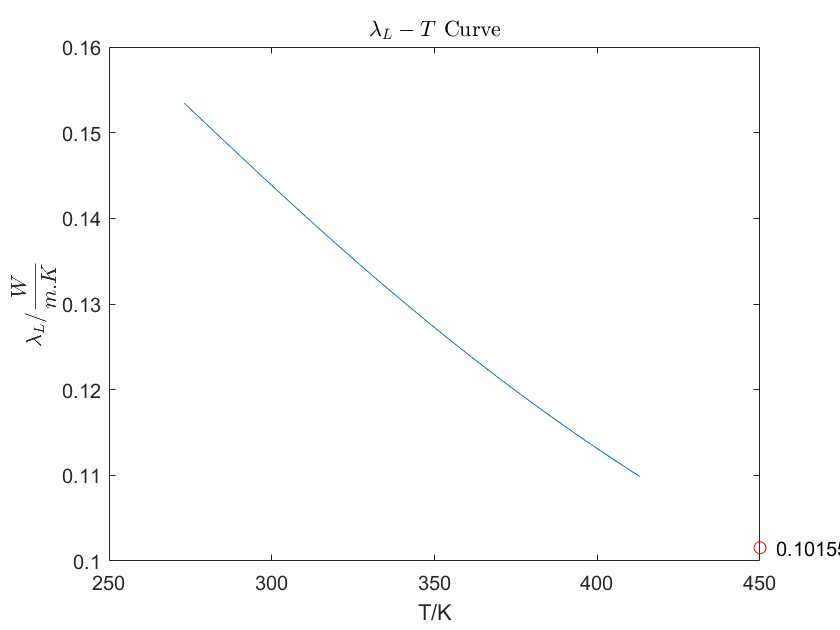

plot([ C6H6.LiquidThermalConductivity(end-1):C6H6.LiquidThermalConductivity(end) ], C6H6.LiquidThermalConductivity_func( [C6H6.LiquidThermalConductivity(end-1):C6H6.LiquidThermalConductivity(end) ] ))
hold on
plot(450,  C6H6.LiquidThermalConductivity_func(450), 'or')
text(455,  C6H6.LiquidThermalConductivity_func(450), num2str(C6H6.LiquidThermalConductivity_func(450)) )
hold off
title('$${\lambda_L-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')
ylabel('$${\lambda_L/ \frac{W}{m.K}}$$', 'Interpreter', 'latex')

- VaporThermalConductivity, 气体导热系数, W/m/K

- 
$$\lambda_V =\frac{A*T^B }{\left(1+\frac{C}{T}+\frac{D}{T^2 }\right)}$$


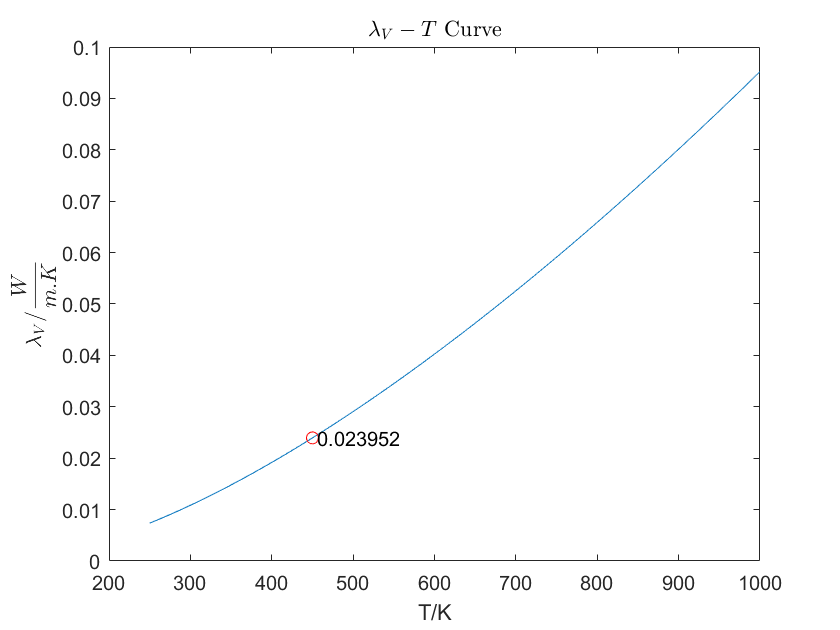

plot([ C6H6.VaporThermalConductivity(end-1):C6H6.VaporThermalConductivity(end) ], C6H6.VaporThermalConductivity_func( [C6H6.VaporThermalConductivity(end-1):C6H6.VaporThermalConductivity(end) ] ))
hold on
plot(450,  C6H6.VaporThermalConductivity_func(450), 'or')
text(455,  C6H6.VaporThermalConductivity_func(450), num2str(C6H6.VaporThermalConductivity_func(450)) )
hold off
title('$${\lambda_V-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')
ylabel('$${\lambda_V/ \frac{W}{m.K}}$$', 'Interpreter', 'latex')

- AntoineVaporPressure, 安托因蒸汽压, Pa

- 
$$P^{\textrm{Antoine}} =e^{\left(A-\frac{B}{\left(C+T\right)}\right)}$$


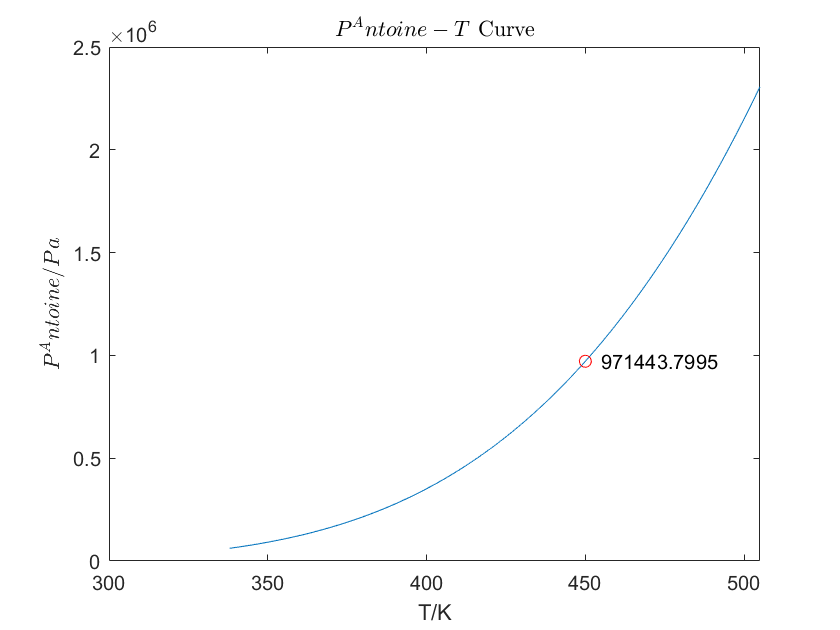

plot([ C6H6.AntoineVaporPressure(end-1):C6H6.AntoineVaporPressure(end) ], C6H6.AntoineVaporPressure_func( [C6H6.AntoineVaporPressure(end-1):C6H6.AntoineVaporPressure(end) ] ))
hold on
plot(450,  C6H6.AntoineVaporPressure_func(450), 'or')
text(455,  C6H6.AntoineVaporPressure_func(450), num2str(C6H6.AntoineVaporPressure_func(450)) )
hold off
title('$${P^Antoine-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')
ylabel('$${P^Antoine/ Pa}$$', 'Interpreter', 'latex')

- SurfaceTension, 表面张力, N/m

- 
$$\sigma \;=A+e^{\left(\frac{B}{T}+C+D*T+E*T^2 \right)}$$


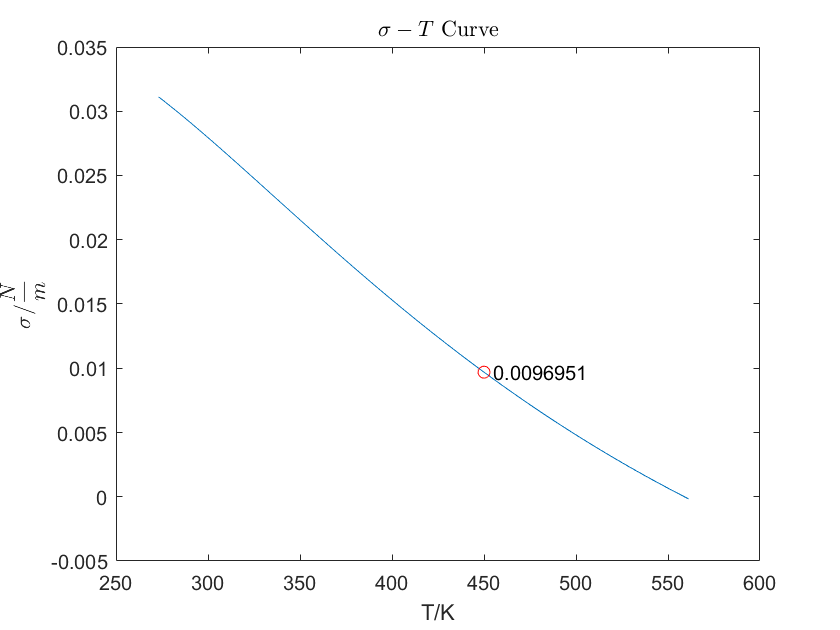

plot([ C6H6.SurfaceTension(end-1):C6H6.SurfaceTension(end) ], C6H6.SurfaceTension_func( [C6H6.SurfaceTension(end-1):C6H6.SurfaceTension(end) ] ))
hold on
plot(450,  C6H6.SurfaceTension_func(450), 'or')
text(455,  C6H6.SurfaceTension_func(450), num2str(C6H6.SurfaceTension_func(450)) )
hold off
title('$${\sigma-T}$$ Curve', 'Interpreter', 'latex')
xlabel('T/K')
ylabel('$${\sigma/ \frac{N}{m}}$$', 'Interpreter', 'latex')

纯物质,丙烷为例,计算体积,逸度系数,焓

format long
CAS = '74-98-6';
% CAS = '75-28-5';
Propane = Component(CAS);
P = 997420;
% P = 2190000;
% P = 2250000
T = 300;
% T = 400;
z = 1;
q = 1;
[Vl,phi,Hl1] = EOS(P,T,z,q,Propane,'PR');


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


q = 0;
[Vv,phi,Hv1] = EOS(P,T,z,q,Propane,'PR');


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



P = 4247700;
T = 369.85;
q = 0;
[Vcritical,phi,Hcritical] = EOS(P,T,z,q,Propane,'PR');


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


混合物,R12(CCl2F2)和R22(CHClF2为例,计算体积,逸度系数,焓

R12 = Propane;
R22 = Propane;
R12.Pc = 4.224*10^6;
R12.Tc = 385;
R12.omega = 0.176;
R22.Pc = 4.975*10^6;
R22.Tc = 369.2;
R22.omega = 0.215;
P = 1.0*10^6;
T = 400;
q = 0;
z = [0.5,0.5];
for P = [1:5]*10^6
    [Vv,phi,Hv] = EOS(P,T,z,q,[R22,R12],'PR');
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

P = 15200000;
T = 310.8;
CH4 = Component('74-82-8');
N2 = Component('7727-37-9');
C2H6 = Component('74-84-0');
z = [0.82,0.10,0.08];
q = 0;
[Vv,phi,Hv] = EOS(P,T,z,q,[CH4,N2,C2H6],'PR');


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



CO2 = Component('124-38-9');
NC4 = Component('106-97-8');
P = 1.061*10^6;
T = 273.15;
z = [0.2,0.8];
q = 1;
[Vl,phi,Hl] = EOS(P,T,z,q,[CO2,NC4],'PR');


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


z = [0.8962,0.1038];
q = 0;
[Vv,phi,Hv] = EOS(P,T,z,q,[CO2,NC4],'PR');


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


function Property = Component(CAS)
    CAS = [CAS, '.json'];
    PropertyParameter = jsondecode(fileread(CAS));
    
    % 系统常数
    % R: 气体常数, 8314, J/kmol/K;
    Property.R = 8.314*1000;
    % Tref: 基准温度, 298.15, K;
    Property.Tref = 298.15;
    % Pref: 基准压力, 101325, Pa;
    Property.Pref = 101325;

    Property.CAS = PropertyParameter.CAS;
    Property.Ename = PropertyParameter.CompoundID;
    Property.StructureFormula = PropertyParameter.StructureFormula;

    % Pc, 临界压力, Pa
    Property.Pc = str2double(PropertyParameter.CriticalPressure(1));
    % Tc, 临界温度, K    
    Property.Tc = str2double(PropertyParameter.CriticalTemperature(1));
    % Vc, 临界体积, m3/kmol
    Property.Vc = str2double(PropertyParameter.CriticalVolume(1));
    % Zc, 临界压缩因子, -
    Property.Zc = str2double(PropertyParameter.CriticalCompressibility(1));
    % Tb, 常压沸点温度, K
    Property.Tb = str2double(PropertyParameter.NormalBoilingPointTemperature(1));
    % Ttriple, 三相点温度, K
    Property.Ttriple = str2double(PropertyParameter.TriplePointTemperature(1));
    % Ptriple, 三相点压力, Pa
    Property.Ptriple = str2double(PropertyParameter.TriplePointPressure(1));
    % Mw, 摩尔质量, kg/kmol
    Property.Mw = str2double(PropertyParameter.MolecularWeight(1));
    % omega, 偏心因子, -
    Property.omega = str2double(PropertyParameter.AcentricityFactor(1));
    % Hform, 标准摩尔生成焓, J/kmol
    Property.Hform = str2double(PropertyParameter.HeatOfFormation(1));
    % Gform, 标准摩尔生成自由能, J/kmol
    Property.Gform = str2double(PropertyParameter.GibbsEnergyOfFormation(1));
    % Sform, 绝对熵, J/kmol/K
    Property.Sform = str2double(PropertyParameter.AbsEntropy(1));
    
    % LiquidDensity, 液体的密度, kmol/m3
    % LiquidDensity_func, DIPPR函数
    PropertyName = 'LiquidDensity';
    group = PropertyParameter.LiquidDensity(1);
    equationNo = group{1}.eqno;
    [Property.LiquidDensity, Property.LiquidDensity_func] = DIPPR(equationNo);
    
    % VaporPressure, 饱和蒸汽压, Pa
    % VaporPressure_func, DIPPR函数
    PropertyName = 'VaporPressure';
    group = PropertyParameter.VaporPressure(1);
    equationNo = group{1}.eqno;
    [Property.VaporPressure, Property.VaporPressure_func] = DIPPR(equationNo);
    
    % HeatOfVaporization, 标准摩尔蒸发焓, J/kmol
    % HeatOfVaporization_func, DIPPR函数
    PropertyName = 'HeatOfVaporization';
    group = PropertyParameter.HeatOfVaporization(1);
    equationNo = group{1}.eqno;
    [Property.HeatOfVaporization, Property.HeatOfVaporization_func] = DIPPR(equationNo);
    
    % LiquidHeatCapacityCp, 液体等压比热容, J/kmol/K
    % LiquidHeatCapacityCp_func, DIPPR函数
    PropertyName = 'LiquidHeatCapacityCp';
    group = PropertyParameter.LiquidHeatCapacityCp(1);
    equationNo = group{1}.eqno;
    [Property.LiquidHeatCapacityCp, Property.LiquidHeatCapacityCp_func] = DIPPR(equationNo);
    
    % IdealGasHeatCapacityCp, 理想气体等压比热容, J/kmol/K
    % IdealGasHeatCapacityCp_func, DIPPR函数
    PropertyName = 'IdealGasHeatCapacityCp';
    group = PropertyParameter.IdealGasHeatCapacityCp(1);
    equationNo = group{1}.eqno;
    [Property.IdealGasHeatCapacityCp, Property.IdealGasHeatCapacityCp_func] = DIPPR(equationNo);
    
    % LiquidViscosity, 液体粘度, Pa.s
    % LiquidViscosity, DIPPR函数
    PropertyName = 'LiquidViscosity';
    group = PropertyParameter.LiquidViscosity(1);
    equationNo = group{1}.eqno;
    [Property.LiquidViscosity, Property.LiquidViscosity_func] = DIPPR(equationNo);
    
    % VaporViscosity, 气体粘度, Pa.s
    % VaporViscosity_func, DIPPR函数
    PropertyName = 'VaporViscosity';
    group = PropertyParameter.VaporViscosity(1);
    equationNo = group{1}.eqno;
    [Property.VaporViscosity, Property.VaporViscosity_func] = DIPPR(equationNo);
    
    % LiquidThermalConductivity, 液体导热系数, W/m/K
    % LiquidThermalConductivity_func, DIPPR函数
    PropertyName = 'LiquidThermalConductivity';
    group = PropertyParameter.LiquidThermalConductivity(1);
    equationNo = group{1}.eqno;
    [Property.LiquidThermalConductivity, Property.LiquidThermalConductivity_func] = DIPPR(equationNo);
    
    % VaporThermalConductivity, 气体导热系数, W/m/K
    % VaporThermalConductivity_func, DIPPR函数
    PropertyName = 'VaporThermalConductivity';
    group = PropertyParameter.VaporThermalConductivity(1);
    equationNo = group{1}.eqno;
    [Property.VaporThermalConductivity, Property.VaporThermalConductivity_func] = DIPPR(equationNo);
    
    % AntoineVaporPressure, 安托因蒸汽压, Pa
    % AntoineVaporPressure_func, DIPPR函数
    PropertyName = 'AntoineVaporPressure';
    group = PropertyParameter.AntoineVaporPressure(1);
    equationNo = group{1}.eqno;
    [Property.AntoineVaporPressure, Property.AntoineVaporPressure_func] = DIPPR(equationNo);
    
    
    % SurfaceTension, 表面张力, N/m
    % SurfaceTension_func, DIPPR函数
    PropertyName = 'SurfaceTension';
    group = PropertyParameter.SurfaceTension(1);
    equationNo = group{1}.eqno;
    [Property.SurfaceTension, Property.SurfaceTension_func] = DIPPR(equationNo);
    
    function [para, func] = DIPPR(equationNo)
        equation = PropertyParameter.(PropertyName)(1);
        Tmin = str2double(equation{1}.Tmin);
        Tmax = str2double(equation{1}.Tmax);
        switch equationNo
            case '1'
                A = str2double(equation{1}.A);
                para = [A,Tmin,Tmax];
                func = @(T) A;
            case '2'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                para = [A,B,Tmin,Tmax];
                func = @(T) A + B.*T;
            case '3'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                para = [A,B,C,Tmin,Tmax];
                func = @(T) A + B.*T + C.*T.^2;
            case '4'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                para = [A,B,C,D,Tmin,Tmax];
                func = @(T) A + B.*T + C.*T.^2 + D.*T.^3;
            case '5'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                E = str2double(equation{1}.E);
                para = [A,B,C,D,E,Tmin,Tmax];
                func = @(T) A + B.*T + C.*T.^2 + D.*T.^3 + E.*T.^4;
            case '6'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                E = str2double(equation{1}.E);
                para = [A,B,C,D,E,Tmin,Tmax];
                func = @(T) A + B.*T + C.*T.^2 + D.*T.^3 + E./T.^2;
            case '10'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                para = [A,B,C,Tmin,Tmax];
                func = @(T) exp(A - B./(C+T)); 
            case '16'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                E = str2double(equation{1}.E);
                para = [A,B,C,D,E,Tmin,Tmax];
                func = @(T) A + exp(B./T + C + D*T + E.*T.^2);
            case '100'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                E = str2double(equation{1}.E);
                para = [A,B,C,D,E,Tmin,Tmax];
                func = @(T) A + B.*T + C.*T.^2 + D.*T.^3 + E.*T.^4;
            case '101'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                E = str2double(equation{1}.E);
                para = [A,B,C,D,E,Tmin,Tmax];
                func = @(T) exp(A + B./T + C.*log(T) + D.*T.^E);
            case '102'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                para = [A,B,C,D,Tmin,Tmax];
                func = @(T) A.*T.^B./(1 + C./T + D./T.^2);
            case '103'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                para = [A,B,C,D,Tmin,Tmax];
                func = @(T) A + B.*exp(-C./T.^D);
            case '104'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                E = str2double(equation{1}.E);
                para = [A,B,C,D,E,Tmin,Tmax];
                func = @(T) A + B./T + C*10^6./T.^3 + D*10^16./T.^8 + E*10^18./T.^9;
            case '105'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                para = [A,B,C,D,Tmin,Tmax];
                func = @(T) A./B.^(1+(1-T/C).^D);
            case '106'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                E = str2double(equation{1}.E);
                para = [A,B,C,D,E,Tmin,Tmax];
                func = @(T) A.*(1-T./Property.Tc).^(B + C.*(T./Property.Tc) + D.*(T./Property.Tc).^2 + E.*(T./Property.Tc).^3);
            case '107'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                E = str2double(equation{1}.E);
                para = [A,B,C,D,E,Tmin,Tmax];
                func = @(T) A + B.*(C./T./sinh(C./T)).^2 + E.*(D./T./cosh(D./T)).^2;
            case '114'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                para = [A,B,C,D,Tmin,Tmax];
                func = @(T) A.*T + B.*T.^2/2 + C.*T.^3/3 + D.*T.^4/4;
            case '117'
                A = str2double(equation{1}.A);
                B = str2double(equation{1}.B);
                C = str2double(equation{1}.C);
                D = str2double(equation{1}.D);
                E = str2double(equation{1}.E);
                para = [A,B,C,D,E,Tmin,Tmax];
                func = @(T) A.*T + B.*(C./T)./tanh(C./T) - D.*(E./T)./tanh(E./T);
        end   
    end
    
end


function [V,phi,H] = EOS(P,T,z,q,Component,flag)
    % Input:
        % P: 压力, Pa, 1*1;
        % T: 温度, K, 1*1;
        % z: 摩尔组成, -, 1*c;
        % q: 相态, 0,气相;1,液相, 1*1;
        % Component: 组分物性参数, -, 1*c;
        % flag: EOS方程, 'RK,SRK,PR', 1*1;
    % Output:
        % V: 摩尔体积, m^3/kmol, 1*1;
        % phi, 组分的逸度系数, -, c*1;
        % H: 焓, J/kmol, 1*1;
        % S: 熵, J/koml/K, 1*1;
        
    % Constant;
    % 理想气体常数: R = 8314, J/koml/K
    R = Component.R;
    % 基准温度: Tref = 298.15, K
    Tref = Component.Tref;
    % 基准压力: Pref = 101325, Pa;
    Pref = Component.Pref;
    
    % 组分数c
    c = length(z);
    % 摩尔组成归一化
    z = z./sum(z);
    
    % 物性参数
    Pc_i = ones(c,1);
    Tc_i = ones(c,1);
    omega_i = ones(c,1);
    Mw_i = ones(c,1);
    Hideal_i = ones(c,1);
    S_temp_i = ones(c,1);
    for i = 1:c
        Pc_i(i) = Component(i).Pc;
        Tc_i(i) = Component(i).Tc;
        omega_i(i) = Component(i).omega;
        Mw_i(i) = Component(i).Mw;
        Hideal_i(i) = integral(Component(i).IdealGasHeatCapacityCp_func, Tref, T);
        S_temp_i(i) = integral(@(T) Component(i).IdealGasHeatCapacityCp_func(T)/T, Tref, T, 'ArrayValued',true);
    end
    
    % 对比温度
    Tr_i = T./Tc_i;
    % 对比压力
    Pr_i = P./Pc_i;
    switch flag
        case 'RK'
            sigma = 1;
            epsilon = 0;
            Omega = 0.08664;
            Psi = 0.42748;
            m_i = (Tr_i.^(-0.25) - 1)./(1-Tr.^0.5);
        case 'SRK'
            sigma = 1;
            epsilon = 0;
            Omega = 0.08664;
            Psi = 0.42748;
            m = [0.480, 1.574, -0.176];
            m_i = [ones(c,1) omega_i omega_i.^2]*m';
        case 'PR'
            sigma = 1+sqrt(2);
            epsilon = 1-sqrt(2);
            Omega = 0.07780;
            Psi = 0.45724;
            m = [0.37464, 1.54226, -0.26992];
            m_i = [ones(c,1) omega_i omega_i.^2]*m';
    end
    alpha_i = (1+m_i.*(1-Tr_i.^0.5) ).^2;
    
    a_i = Psi.*R.^2.*Tc_i.^2./Pc_i.* alpha_i; 
    b_i = Omega*R.*Tc_i./Pc_i;
    
    % k,二元交互参数, c*c矩阵
    k_ij = 0;
    
    % 混合规则的选择
    a_ij = (a_i*a_i').^0.5.*(1-k_ij);
    b_ij = (b_i+b_i)/2;
    
    a = z*a_ij*z';
    b = z*b_ij;
    
    switch q
        case 0
            % 气相体积根
            f = @(V) R*T/P + b - a/P*(V-b)/( (V+epsilon*b) * (V+sigma*b) ) - V;
            V = fsolve(f, R*T/P);
        case 1
            % 液相体积根
            f = @(V) b + (V+epsilon*b) * (V+sigma*b) * (R*T + b*P - V*P)/a - V;
            V = fsolve(f, b);
    end
    
    % 混合物的压缩因子Z
    Z = P*V/R/T;
    
    % 定义q,beta,I
    q = a/b/R/T;
    beta = b*P/R/T;
    I = 1/(sigma-epsilon)*log( (Z+sigma*beta)/(Z+epsilon*beta) );
    
    
    % 计算混合物的焓
    
    % 混合理想气体在研究态工况下的焓
    Hideal = z*Hideal_i;
    % 偏离焓的计算
    dalpha_idT = -m_i.*sqrt(Tr_i./alpha_i);
    HR_i = R.*T.*(Z-1+q.*I.*(dalpha_idT-1));
    HR = z*HR_i;
    H = Hideal + HR;

    % 熵的计算目前还存在问题
    % 计算混合物的熵
    SR_i = log(Z-beta) + dalpha_idT.*q.*I;
    SR = z*SR_i;

    % 计算混合物中组分i的系数系数
    db_idn = b_i;
    dq_idn = q.*(2*a_ij*z'./a-b_i./b);
    phi = exp(db_idn./b.*(Z-1) - log(Z-beta) - dq_idn.*I);
    
end
